clear all
clc
clf

%get inital angle based on initial points
%get initial speed based on opencv
%predict position it will land
x = [0,1,2,3,4,5,6];
y = [5,7,5,3,0.5,-2.5,-9];
y = y+17

y =    22.0000   24.0000   22.0000   20.0000   17.5000   14.5000    8.0000


plot(x,y,"x")
g = 9.81

g = 9.8100

ini_vel = .02 %in ms

ini_vel = 0.0200

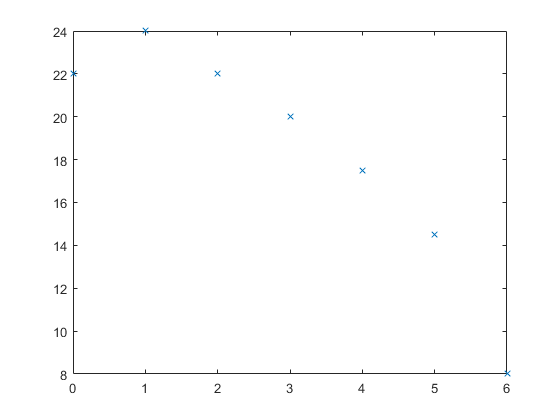


hold on

    ini_angle = atan((y(2)-y(1))/(x(2)-x(1)))

ini_angle = 1.1071

    ang_deg = 180*ini_angle/pi

ang_deg = 63.4349

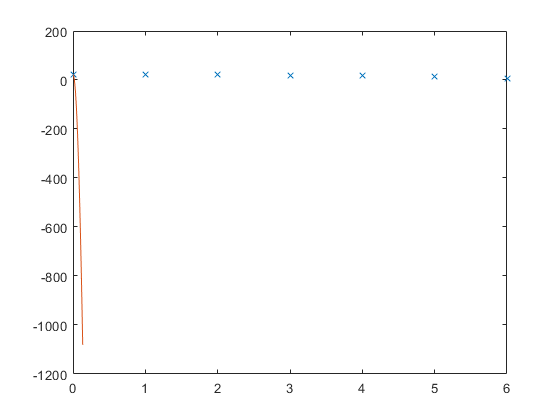

    Vo = ini_vel;
    time =  15;
    t = 0:0.1:time;
    
    y0 = y(1); 
   
   
    Theta = ini_angle;

    x0 = x(1);
   
    x_pred = x0+Vo*cos(Theta)*t;
    y_pred = y0+Vo*sin(Theta)*t-(g*t.^2)/2;
    plot (x_pred,y_pred)